Iterations = 1000000;
Rolls = zeros(2,Iterations)

Rolls =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Adv = zeros(1,20)

Adv =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Dis = zeros(1,20)

Dis =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


Ext = zeros(1,20)

Ext =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0





for i = 1:Iterations
    r = randi(20,1,2);
    Rolls(:,i) = r;
    Adv(max(r)) = Adv(max(r))+1;
    Dis(min(r)) = Dis(min(r))+1;

    if(abs(r(1)-10.5)>abs(r(2)-10.5))
        Ext(r(1)) = Ext(r(1))+1;
    elseif(abs(r(1)-10.5)<abs(r(2)-10.5))
        Ext(r(2)) = Ext(r(2))+1;
    else
        Ext(max(r)) = Ext(max(r))+1;
    end
end


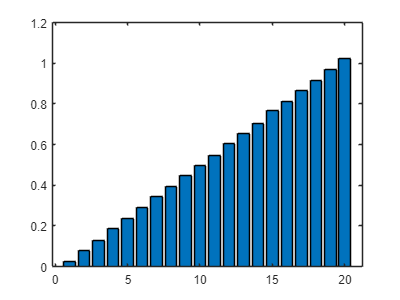


bar(Adv/(Iterations/10.5))

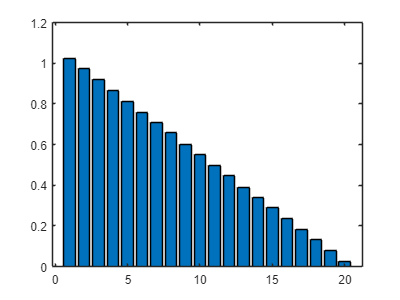

bar(Dis/(Iterations/10.5))

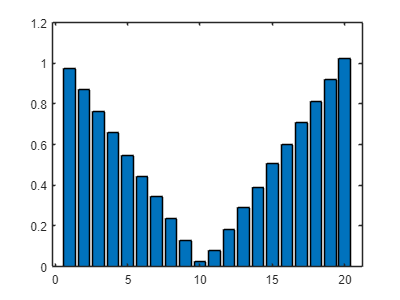

bar(Ext/(Iterations/10.5))

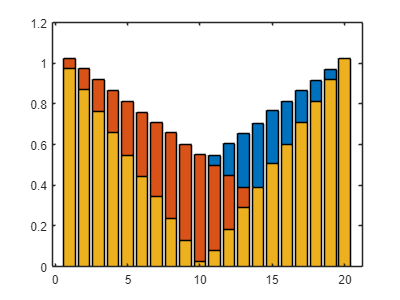


bar(Adv/(Iterations/10.5))
hold on
bar(Dis/(Iterations/10.5))
bar(Ext/(Iterations/10.5))